## Inputting

% Input video file which needs to be stabilized.
filename = 'shaky_car.avi';

hVideoSource = VideoReader(filename);
hTM = vision.TemplateMatcher('ROIInputPort', true, ...
    'BestMatchNeighborhoodOutputPort', true);
hVideoOut = vision.VideoPlayer('Name', 'Video Stabilization');

## **Initializing Parameters**

pos.template_orig = [109 100]; % [x y] upper left corner
pos.template_size = [22 18];   % [width height]
pos.search_border = [10 5];   % max horizontal and vertical displacement
pos.template_center = floor((pos.template_size-1)/2);
pos.template_center_pos = (pos.template_orig + pos.template_center - 1);
W = hVideoSource.Width; % Width in pixels
H = hVideoSource.Height; % Height in pixels
BorderCols = [1:pos.search_border(1)+4 W-pos.search_border(1)+4:W];
BorderRows = [1:pos.search_border(2)+4 H-pos.search_border(2)+4:H];
sz = [W, H];
TargetRowIndices = ...
    pos.template_orig(2)-1:pos.template_orig(2)+pos.template_size(2)-2;
TargetColIndices = ...
    pos.template_orig(1)-1:pos.template_orig(1)+pos.template_size(1)-2;
SearchRegion = pos.template_orig - pos.search_border - 1;
Offset = [0 0];
Target = zeros(18,22);
firstTime = true;

## Processing Loop

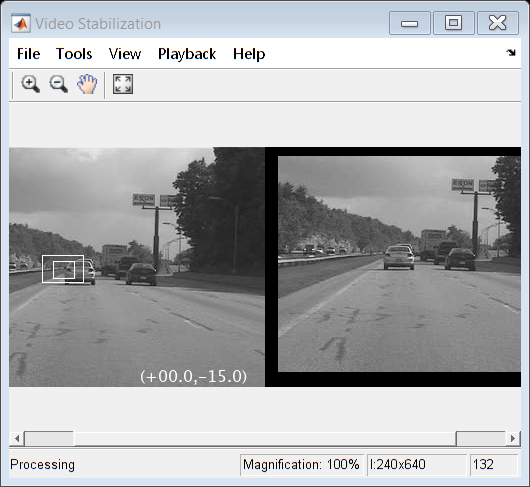

outputVideo = VideoWriter('stabilized_video.avi');
open(outputVideo);
while hasFrame(hVideoSource)
    input = rgb2gray(im2double(readFrame(hVideoSource)));
    
    % Find location of Target in the input video frame
    if firstTime
        Idx = int32(pos.template_center_pos);
        MotionVector = [0 0];
        firstTime = false;
    else
        IdxPrev = Idx;
        
        ROI = [SearchRegion, pos.template_size+2*pos.search_border];
        Idx = hTM(input,Target,ROI);
        
        MotionVector = double(Idx-IdxPrev);
    end
    
    [Offset, SearchRegion] = updatesearch(sz, MotionVector, ...
        SearchRegion, Offset, pos);
    
    % Translate video frame to offset the camera motion
    Stabilized = imtranslate(input, Offset, 'linear');
    
    Target = Stabilized(TargetRowIndices, TargetColIndices);
    
    % Add black border for display
    Stabilized(:, BorderCols) = 0;
    Stabilized(BorderRows, :) = 0;
    
    TargetRect = [pos.template_orig-Offset, pos.template_size];
    SearchRegionRect = [SearchRegion, pos.template_size + 2*pos.search_border];
    
    % Draw rectangles on input to show target and search region
    input = insertShape(input, 'rectangle', [TargetRect; SearchRegionRect],...
        'Color', 'white');
    % Display the offset (displacement) values on the input image
    txt = sprintf('(%+05.1f,%+05.1f)', Offset);
    input = insertText(input(:,:,1),[191 215],txt,'FontSize',16, ...
        'TextColor', 'white', 'BoxOpacity', 0);
    % Display video
    hVideoOut([input(:,:,1) Stabilized]);
    writeVideo(outputVideo, Stabilized);
end

close(outputVideo);